alpha = 0.3; % (rads)
beta  = 0.1; % (rads)
gamma = 0.2; % (rads)

x = 20 % (mm)
y = 20 % (mm)
z = 20 % (mm)

axang2quat()

## Parameters

angles = [ alpha beta gamma]; % Euler Angles 
position = [ x y z];  % Centroid Position 

## Transformations

rotm = eul2rotm(angles);
th = trvec2tform(position) *  rotm2tform(rotm); % Create 

## Box Collision parameters

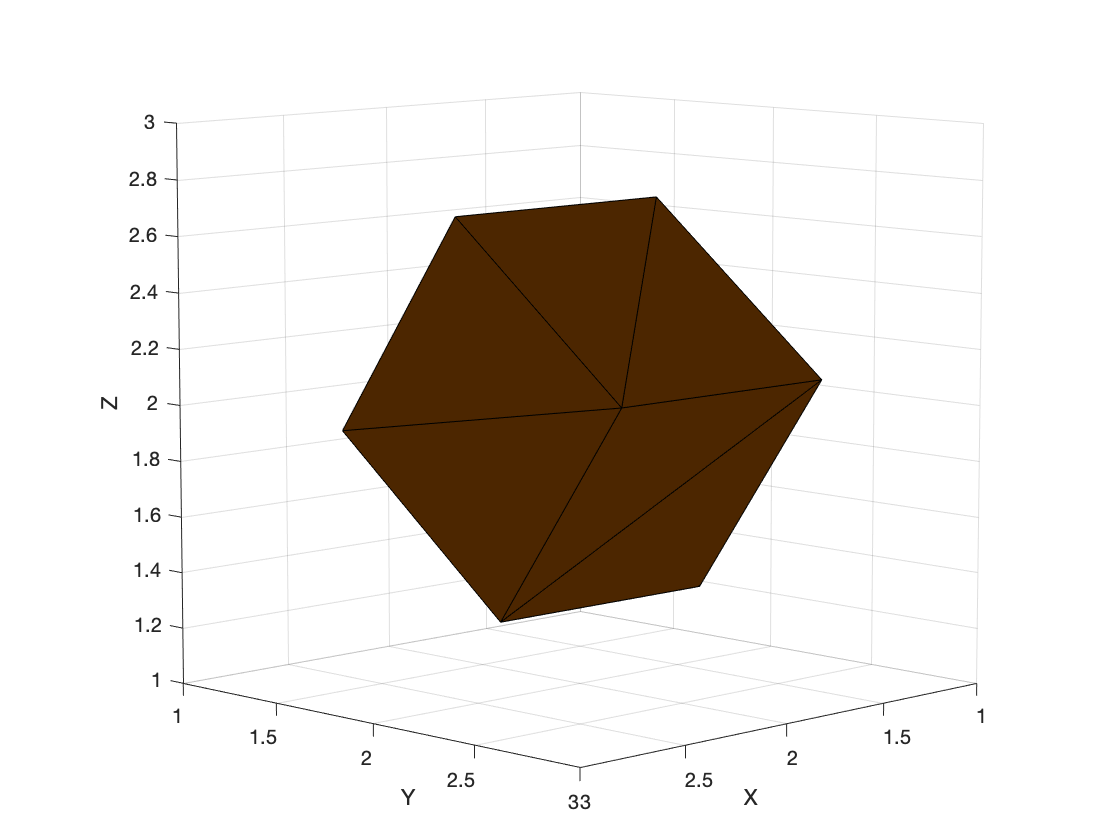

H= 1;  % Height  (mm)
R = 0.5 ; % Radius (mm)

% Create collision box -------------
cb = collisionBox(2 * R , 2 * R, H); 
cb.Pose = cb.Pose * th; % State the new pose from Homogenous trans. 

show(cb)